# 繪圖軟體應用 第10周(11/13) 

配合課本CH7

## ETOPO5 5-minute gridded elevation data

[https://www.ngdc.noaa.gov/mgg/global/relief/ETOPO5/](https://www.ngdc.noaa.gov/mgg/global/relief/ETOPO5/)

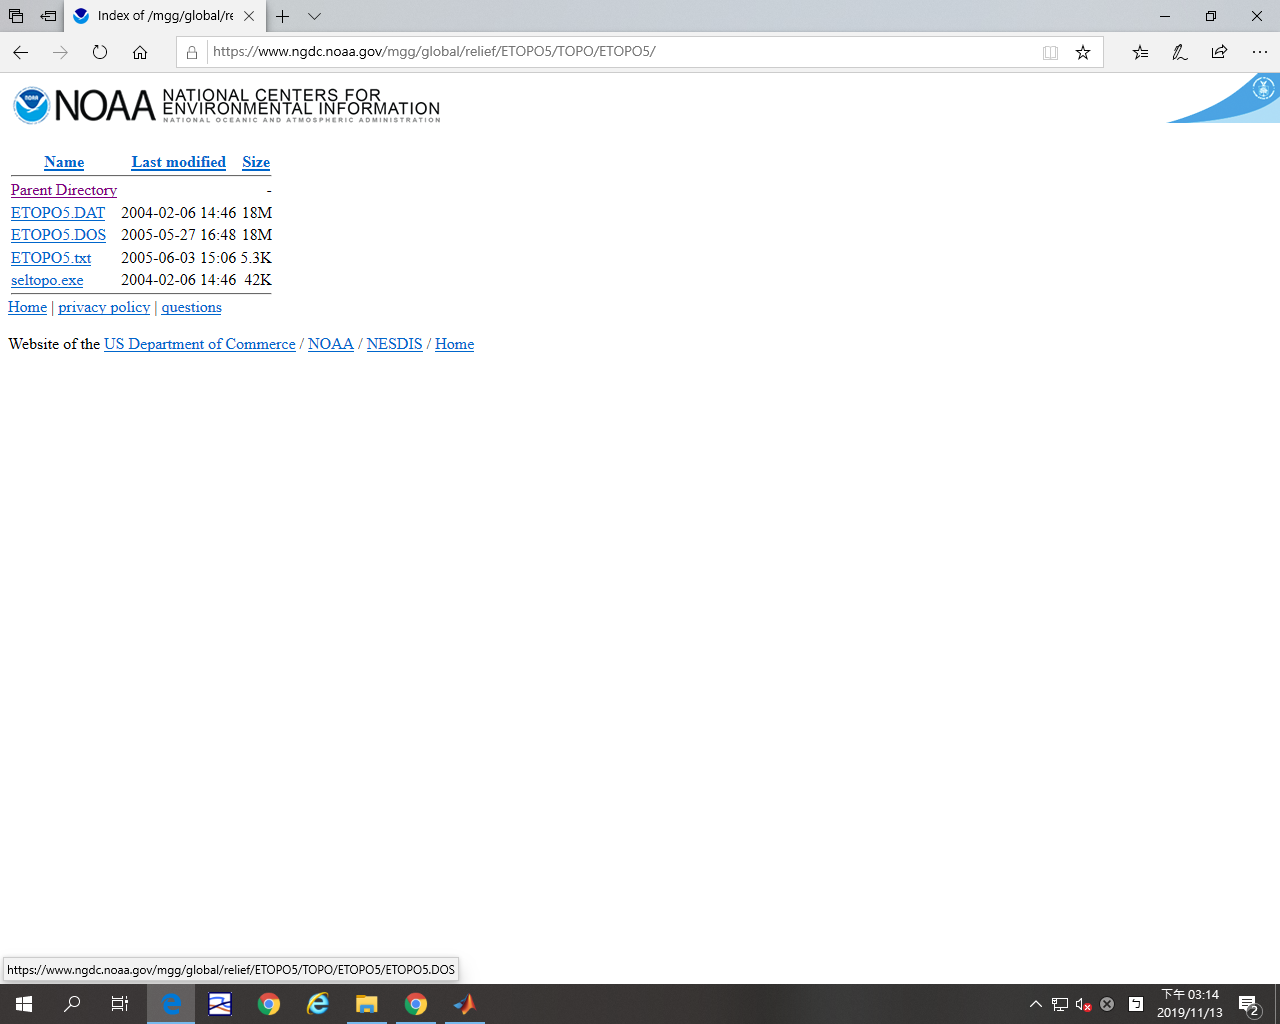

下載 [ETOPO5.DOS](https://www.ngdc.noaa.gov/mgg/global/relief/ETOPO5/TOPO/ETOPO5/ETOPO5.DOS) ，[seltopo.exe](https://www.ngdc.noaa.gov/mgg/global/relief/ETOPO5/TOPO/ETOPO5/seltopo.exe)

開啟 [seltopo.exe](https://www.ngdc.noaa.gov/mgg/global/relief/ETOPO5/TOPO/ETOPO5/seltopo.exe) 在執行檔中輸入經緯度範圍(NW、SE)

最後得到一個dat檔

用記事本將dat檔開啟，把檔案前後不需要的資訊(文字)刪除

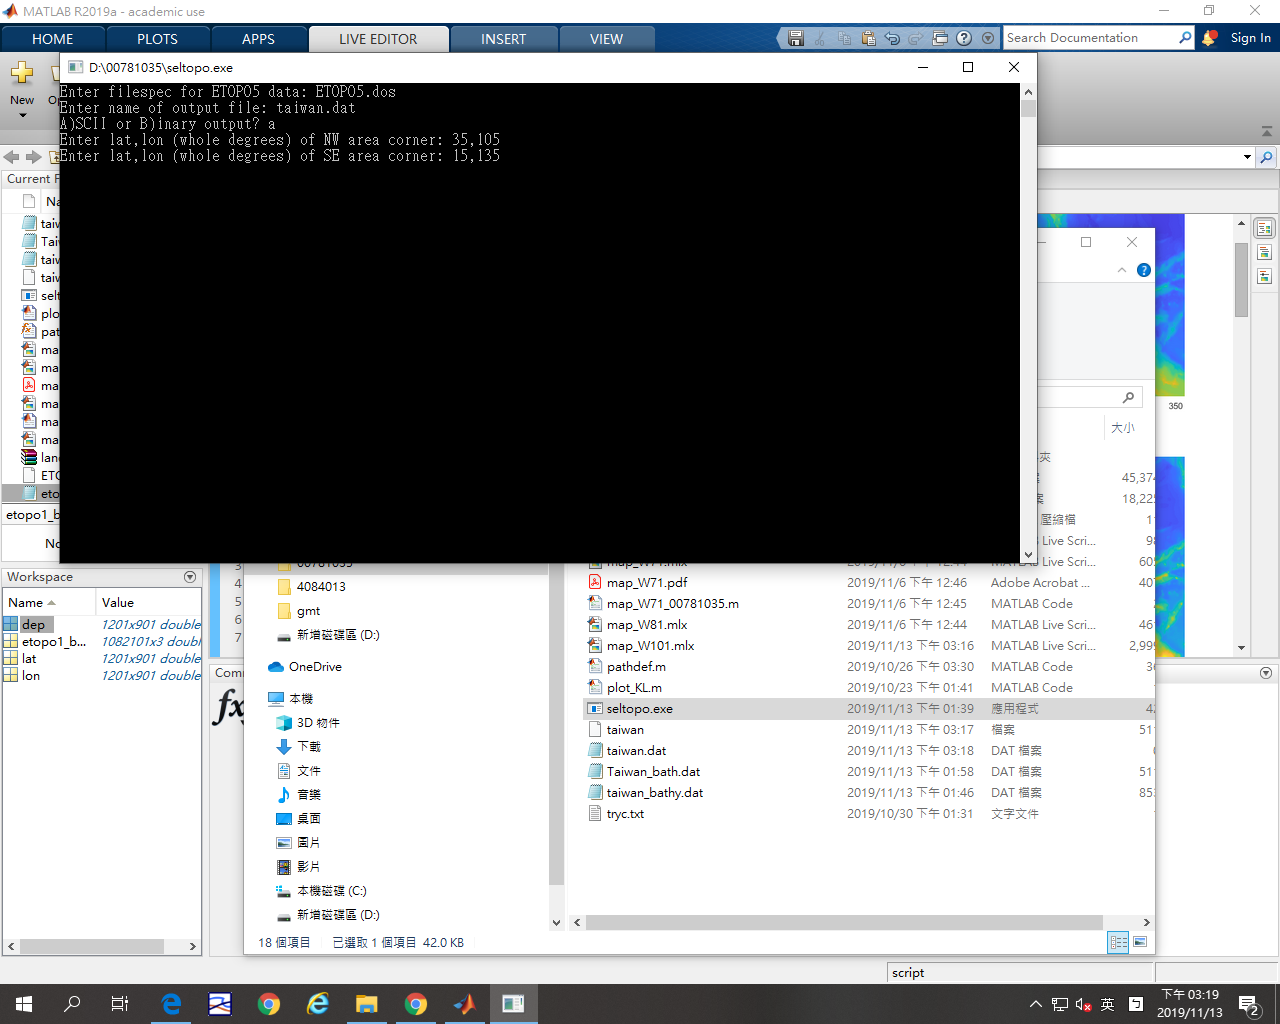

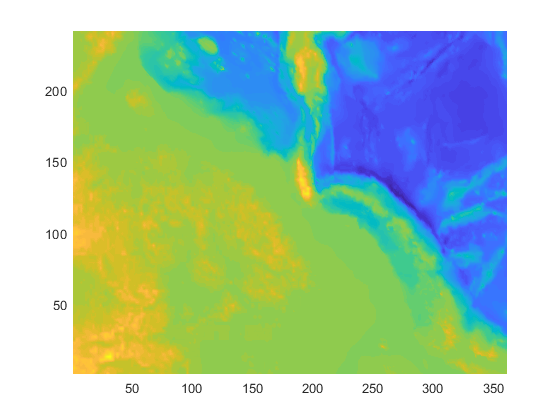

clear;clc;clf
load taiwan.dat 
figure(1)
pcolor(taiwan);shading interp

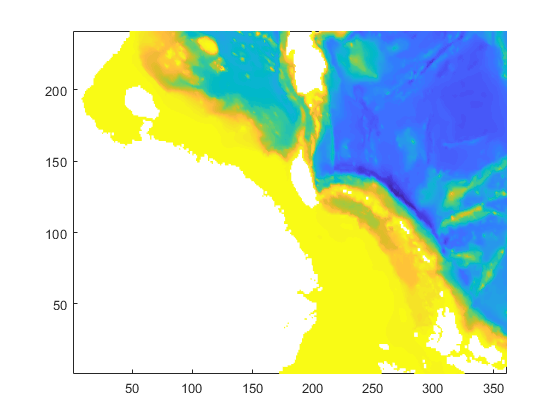

figure(2)
taiwan(taiwan >= 0) =nan; %去除海平面以上的值
pcolor(taiwan);shading interp

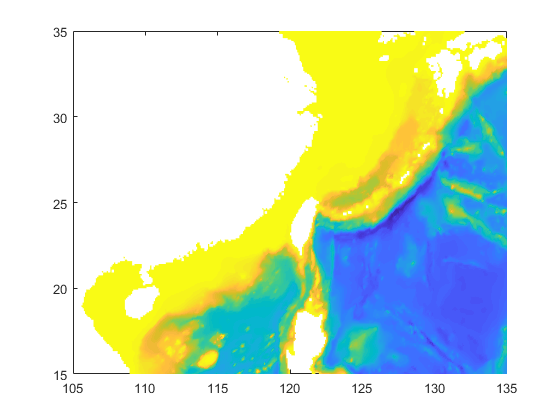

figure(3)
taiwan(taiwan >= 0) =nan; %去除海平面以上的值
lon = 105:5/60:135;
lat = 35:-5/60:15;
[xx,yy] = meshgrid(lon,lat);
pcolor(xx,yy,taiwan);shading interp

lon = 105:5/60:135

lat = 35:-5/60:15;

[xx,yy] = meshgrid(x,y)

pcolor(xx,yy,taiwan)

## 作業 : 改變用taiwan.dat 畫圖的座標排序與數值

ETOPO5只有給高度的向量(z向量)，沒有提供經緯度

因為MATLAB以行向量繪圖，所以和所期望的樣子有偏差

將原本的圖改用經緯度呈現座標並且上下翻轉圖片

## ETOPO1 Global Relief Model

[https://www.ngdc.noaa.gov/mgg/global/global.html](https://www.ngdc.noaa.gov/mgg/global/global.html)

ETOPO1提供了經緯度、高度的向量(x,y,z向量)

 [Grid Extract Tool](https://maps.ngdc.noaa.gov/viewers/wcs-client/)

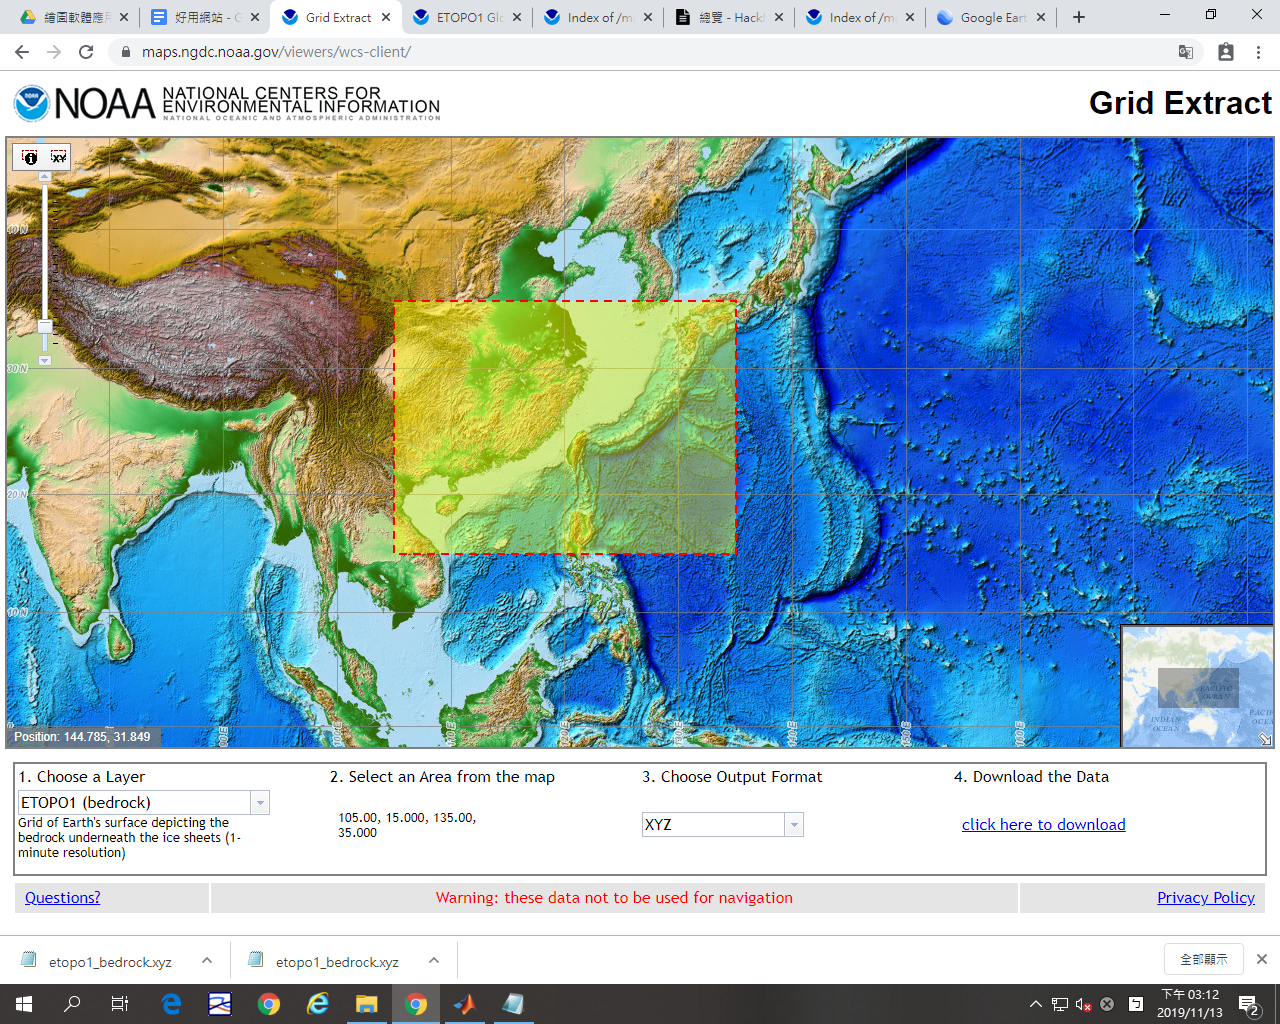

在 [Grid Extract Tool](https://maps.ngdc.noaa.gov/viewers/wcs-client/)網站上選取經緯度範圍

下載 etopo1_bedrock.xyz

clear;clc;clf
load etopo1_bedrock.xyz %(30,110)、(15,130)
whos

  Name                      Size               Bytes  Class     Attributes

  etopo1_bedrock      1082101x3             25970424  double              



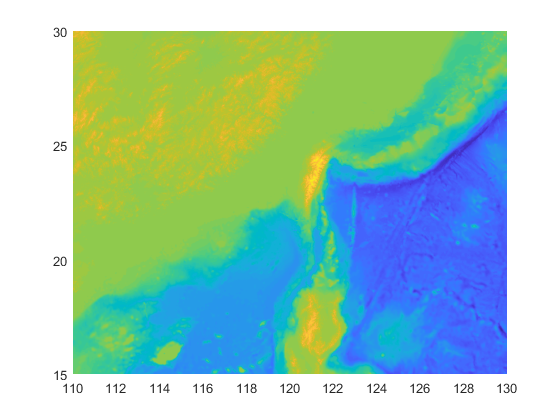

% 3153601 = 2101*1501
% 1082101 = 901*1201
lon = reshape(etopo1_bedrock(:,1),1201,901);
lat = reshape(etopo1_bedrock(:,2),1201,901);
dep = reshape(etopo1_bedrock(:,3),1201,901);
figure(1)
pcolor(lon,lat,dep);

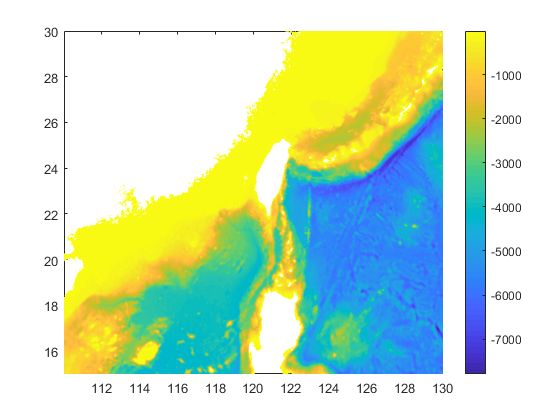

shading flat %必需的
figure(2)
dep(dep >= 0) = nan; %去除海平面以上的資料
pcolor(lon,lat,dep);shading flat
colorbar('v')

向量場繪製

clear;clc;clf
x = 1:3

x =      1     2     3


y = 1:3

y =      1     2     3


[xx,yy] = meshgrid(x,y)

xx =      1     2     3
     1     2     3
     1     2     3


yy =      1     1     1
     2     2     2
     3     3     3


u = [0 0 0;0 1 0;0 0 0]

u =      0     0     0
     0     1     0
     0     0     0


v = zeros(3)

v =      0     0     0
     0     0     0
     0     0     0


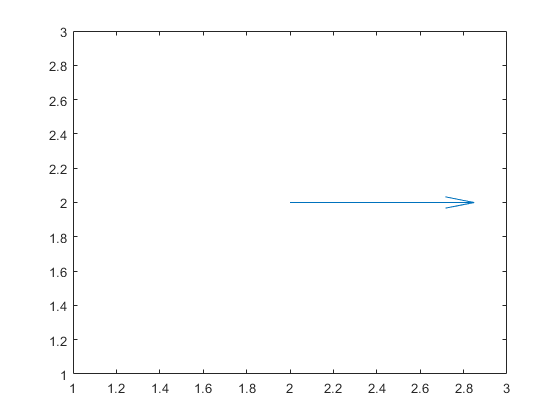


quiver(xx,yy,u,v)

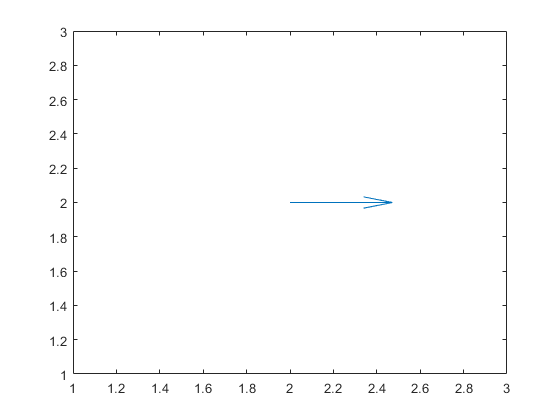

quiver(xx,yy,u,v,0.5) %箭頭長短

長條圖

pie圖

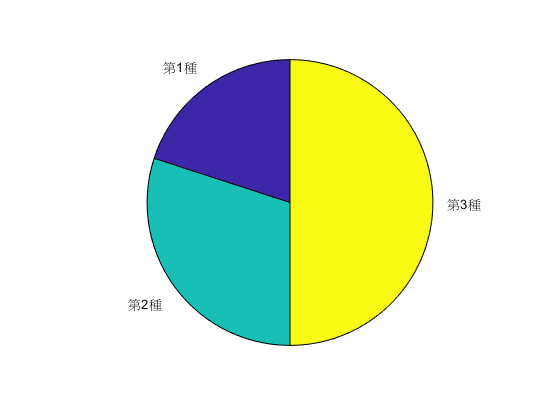

clear;clc;clf
x = [0.2 0.3 0.5];
labels = {'第1種','第2種','第3種'};
pie(x,labels)

直方圖hist(data)

動畫的製作

nframe()

getframe()

movie()

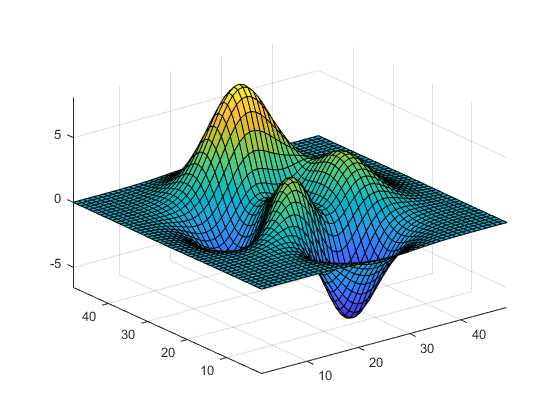

clear;clc;clf
Z = peaks;
surf(Z)
axis tight manual

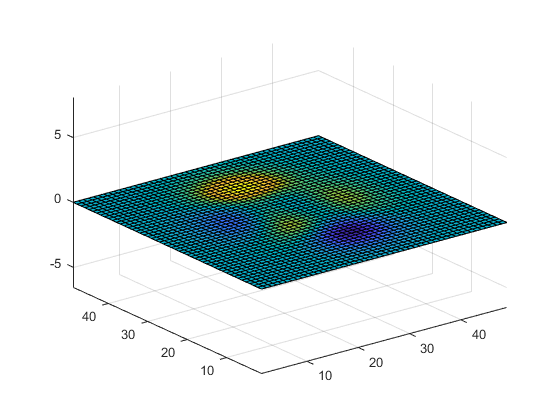

ax = gca;
ax.NextPlot = 'replaceChildren';

loops = 40;
F(loops) = struct('cdata',[],'colormap',[]);
for j = 1:loops
    X = sin(j*pi/10)*Z;
    surf(X,Z)
    drawnow
    F(j) = getframe(gcf);
end